# Complex Numbers 

Complex numbers are extention of real numbers and were introduced first time to include solusions for cirtain equations that do not have real solution. Later many applications were found in science and engineering using these numbers. 

A complex number is a number of the form ***a*****+*****bi*****,** where ***a*** and ***b*** are real numbers, and ***i*** is the imaginary unit. The imaginary unit is defined as ***i^*****2=−1**.

% Defining a complex number
realPart = 1;
imgPart = 3;
z = complex(realPart,imgPart)

z = 1.0000 + 3.0000i

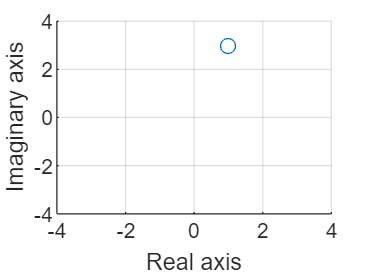


figure
grid on
hold on
plot(realPart,imgPart,'o')
xlabel('Real axis')
ylabel('Imaginary axis')
xlim([-4 4])
ylim([-4 4])
hold off

**Complex Sine Waves**

Any point in polar coordinates is determined by ***r***, the length of the line that connects the point to the origin, and ***θ***, the angle between that line and the horizontal axis. Any point in the Cartesian plane can be converted to polar coordinates with the following formulas:


$$x= r \cdot \cos(\theta)
$$



$$y = r \cdot \sin(\theta)
$$


In the complex plane, *y* is replaced with the imaginary axis. So, we can write:


$$a= r \cdot \cos(\theta)
$$



$$b= r \cdot \sin(\theta)
$$


Therefore, in the complex plane:


$$z = r \cdot \cos(\theta) + r \cdot \sin(\theta) \cdot i = r \cdot ( \cos(\theta) + i \cdot \sin(\theta) )
$$


When ***θ*** is a function of time, this formula gives us a trajectory in three dimensions, which we call a complex sine wave.

We can rewrite the complex sine wave formula using Euler's formula:


$$r \cdot e^{i \cdot \theta} = r \cdot (\cos(\theta) + i \cdot \sin(\theta))
$$


Euler's formula relates the exponential function to trigonometric functions and is commonly used to express complex numbers. It provides a concise way to represent sinusoidal functions in the complex plane.

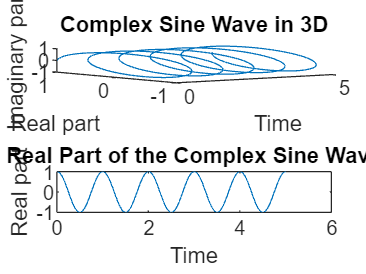

% Define the time vector
time = 0:0.01:5;

% Calculate the complex sine wave
frequency = 1; % Adjust the frequency as needed
comSinWav = exp(1i * 2 * pi * frequency * time); % Using 2*pi*f*t for one full cycle

% Plotting a complex sine wave in 3D
figure;
subplot(2, 1, 1);
plot3(time, real(comSinWav), imag(comSinWav))
xlabel('Time')
ylabel('Real part')
zlabel('Imaginary part')
title('Complex Sine Wave in 3D')

% Plotting real part of the complex sine wave
subplot(2, 1, 2);
plot(time, real(comSinWav))
xlabel('Time')
ylabel('Real part')
title('Real Part of the Complex Sine Wave')

# Fourier Transformation

The Fourier transform is a mathematical operation that decomposes a function into its constituent frequency components. Any continuous function can be approximated using a series of **weighted sine waves**. In the context of signals, it allows us to represent a signal in terms of the frequencies it contains. The Fourier transform is particularly useful for analyzing periodic signals and understanding their frequency content.

We can find weights or coefficients of Fourier transform using this integral:


$$X(\omega) = \int_{-\infty}^{\infty} x(t) \cdot e^{-j\omega t} \, dt
$$


$X(\omega) 
$ gives us ives the weight or coefficient associated with each frequency *ω.*

%% creating a wave composed of different frequencies
Fs = 100; % Sampling frequency (Hz)
t = 0:1/Fs:1; % Time vector (1 second duration)
frequencies = [5, 10, 20]; % Frequencies of sine waves (Hz)

% Initialize signal
x = zeros(size(t));

% Generate sine waves of different frequencies and add them together
for freq = frequencies
    x = x + sin(2*pi*freq*t);
end

% Plot the signal in the time domain
figure;
subplot(2,1,1);
plot(t, x);
xlabel('Time (s)');
ylabel('Amplitude');
title('Time Domain Signal');

%% Compute and plot the Fourier Transform
N = length(x); % Length of the signal
X = fft(x)/N; % Compute Fourier Transform and normalize
freq_axis = Fs*(0:(N/2))/N; % Compute frequency axis
single_sided_spectrum = abs(X(1:N/2+1)); % Extract single-sided spectrum

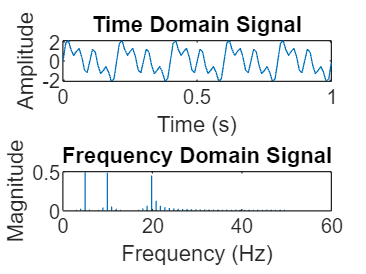


subplot(2,1,2);
stem(freq_axis, single_sided_spectrum, 'Marker', 'none');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Frequency Domain Signal');

**Convolution Theorem:**

The convolution theorem states that convolution in the time domain corresponds to multiplication in the frequency domain.

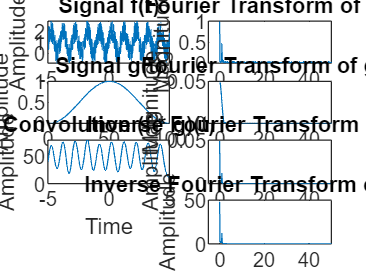

% Define two example signals
t = -5:0.01:5;  % Time vector
l = length(t); % Lenght of the signal
f = sin(2*pi*1*t) + 2*rand(1,length(t));  % Example signal 1: a sine wave + random noise
g = hann(100);   % Example signal 2: a hanning kernel

% Plot the two signals in time domain
figure;
subplot(4, 2, 1);
plot(t, f);
title('Signal f(t)');
xlabel('Time');
ylabel('Amplitude');

subplot(4, 2, 3);
plot(g);
title('Signal g(t)');
xlabel('Time');
ylabel('Amplitude');

% Convolution in the time domain (low-pass filter)
convolution_result = conv(f, g, 'same');
t_conv = t;

% plotting the convolved signal in time domain
subplot(4, 2, 5);
plot(t_conv, convolution_result);
title('Convolution (f * g)(t)');
xlabel('Time');
ylabel('Amplitude');

% Fourier transforms and frequency domain multiplication
NFFT = 2.^nextpow2(l);
F = fft(f,NFFT)/l;
G = fft(g,NFFT)/l;
FxG = F'.*G;
freqs =Fs/2*linspace(0,1,NFFT/2+1);


% ploting signals in frequency domain
subplot(4, 2, 2);
plot(freqs, abs(F(1:NFFT/2+1)));
title('Fourier Transform of f(t)');
xlabel('Frequency');
ylabel('Magnitude');
xlim([-5 50 ]);

subplot(4, 2, 4);
plot(freqs, abs(G(1:NFFT/2+1)));
title('Fourier Transform of g(t)');
xlabel('Frequency');
ylabel('Magnitude');
xlim([-5 50 ]);

subplot(4, 2, 6);
plot(freqs,abs(FxG(1:NFFT/2+1)));
title('Inverse Fourier Transform (F * G)(t)');
xlabel('Time');
ylabel('Amplitude');
xlim([-5 50 ]);

% Plotting Fourier transfrom of the convolved signal
subplot(4, 2, 8);
fourTransConv = fft(convolution_result,NFFT)/l;
plot(freqs,abs(fourTransConv(1:NFFT/2+1)))
title('Inverse Fourier Transform conv(f,g)');
xlabel('Time');
ylabel('Amplitude');
xlim([-5 50 ]);